clear
close all
clc

% Load OCP data from Excel files
file1 = 'E(Imax) Non Pitting.xlsx';
file2 = 'E(Imax) Pitting.xlsx';

% Read OCP data from both Excel files
E_Imax_non_pitting = xlsread(file1, 1);  % Assuming data is in the first sheet
E_Imax_pitting = xlsread(file2, 1);  % Assuming data is in the first sheet

% Define the bin edges between -0.6 and -0.2 V with 0.03 V spacing
edges = 0:0.1:1.5;

% Compute the histogram counts for each data set
counts_non_pitting = histcounts(E_Imax_non_pitting, edges);
counts_pitting = histcounts(E_Imax_pitting, edges);

% Compute the total count for each dataset to find the ratios
total_count_non_pitting = sum(counts_non_pitting);
total_count_pitting = sum(counts_pitting);

% Compute the ratio by dividing each count by the total count
ratio_non_pitting = counts_non_pitting / total_count_non_pitting;
ratio_pitting = counts_pitting / total_count_pitting

ratio_pitting =          0         0         0         0    0.0256    0.0769    0.1795    0.1538    0.1538    0.2821    0.0513    0.0769         0         0         0


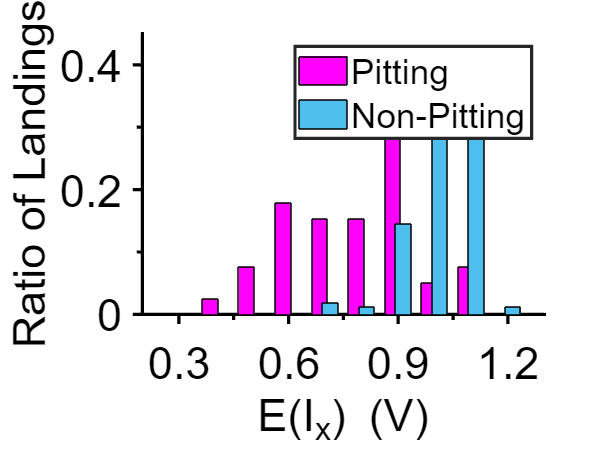

% Calculate the x-coordinates for the bars
x = edges(1:end-1);
bar_width = 1.5;

% Plot the histogram
figure;
hold on;

% Plot the bars on top of each other
bar(x, [ratio_pitting; ratio_non_pitting], bar_width, 'grouped');


xlim([0.2 1.3])
xticks(0.3:0.3:1.5)  % Major ticks

ylim([0 0.45])
yticks(0:0.2:0.6)

set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'off', ...  % Turn off YMinorTick
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 1, ...
    'FontSize', 28, 'linewidth', 2, 'FontWeight', 'normal', ...
    'YTickLabel', get(gca, 'YTickLabel'));


xlabel('E(I_m_a_x) (V)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28,'Color','black')
ylabel('Ratio of Landings', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28,'Color','black')

h = gca; % Get axis to modify
h.XAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.XAxis.MinorTickValues = 0.45:0.3:1.5; % Minor ticks which don't line up with majors

h.YAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.YAxis.MinorTickValues = 0.1:0.2:0.6; % Minor ticks which don't line up with majors

newcolors = {'#FF00FF','#4DBEEE'};
colororder(newcolors)
%axis equal;  % Makes the x-axis and y-axis have the same length
legend('Spreading','Not Spreading','FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 22);

% Plot distribution curves over the histogram

% Fit normal distribution to the data
pd_non_pitting = fitdist(E_Imax_non_pitting, 'Normal');
pd_pitting = fitdist(E_Imax_pitting, 'Normal');

% Generate values for plotting the probability distribution
x_values = linspace(min([E_Imax_non_pitting; E_Imax_pitting]), max([E_Imax_non_pitting; E_Imax_pitting]), 100);

% Normal distribution curves
y_non_pitting = pdf(pd_non_pitting, x_values);
y_pitting = pdf(pd_pitting, x_values);

% Normalize to match the height of the histogram
y_non_pitting = y_non_pitting / max(y_non_pitting) * max(ratio_non_pitting);
y_pitting = y_pitting / max(y_pitting) * max(ratio_pitting);

% Plot the normal distribution curves
%plot(x_values, y_non_pitting, 'LineWidth', 2, 'Color', '#FF00FF', 'LineStyle', '-.');
%plot(x_values, y_pitting, 'LineWidth', 2, 'Color', '#4DBEEE', 'LineStyle', '-.');


% Optional: Fit and plot log-normal distribution
pd_lognon_pitting = fitdist(E_Imax_non_pitting, 'Lognormal');
pd_log_pitting = fitdist(E_Imax_pitting, 'Lognormal');

% Log-normal distribution curves
y_lognon_pitting = pdf(pd_lognon_pitting, x_values);
y_log_pitting = pdf(pd_log_pitting, x_values);

% Normalize to match the height of the histogram
y_lognon_pitting = y_lognon_pitting / max(y_lognon_pitting) * max(ratio_non_pitting);
y_log_pitting = y_log_pitting / max(y_log_pitting) * max(ratio_pitting);

% Plot the log-normal distribution curves
%plot(x_values, y_lognon_pitting, 'LineWidth', 2, 'Color', '#FF00FF', 'LineStyle', '-.');
%plot(x_values, y_log_pitting, 'LineWidth', 2, 'Color', '#4DBEEE', 'LineStyle', '-.');

legend('Pitting','Non-Pitting','FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 22);